# Connect to a ROS Network

A ROS network consists of a single *ROS master* and multiple *ROS nodes*. The ROS master facilitates the communication in the ROS network by keeping track of all active ROS entities. Every node needs to register with the ROS master to be able to communicate with the rest of the network. MATLAB® can start the ROS master, or the master can be launched outside of MATLAB (for example in our virtual machine that is running ROS).

When you work with ROS, you typically follow these steps:

- *Connect to a ROS network*. To connect to a ROS network, you can create the ROS master in MATLAB or connect to an existing ROS master. In both cases, MATLAB will also create and register its own ROS node (called the MATLAB *global node*) with the master. The [`rosinit`](docid:ros_ref.bupf5_j_1) function manages this process.

- *Exchange data*. Once connected, MATLAB exchanges data with other ROS nodes through publishers, subscribers, and services. 

- *Disconnect from the ROS network*. Call the [`rosshutdown`](docid:ros_ref.bupf5_j_8) function to disconnect MATLAB from the ROS network. 

This example shows you how to:

- Create a ROS master in MATLAB

- Connect to an external ROS master

Prerequisites: [Get Started with ROS](docid:ros_ug.mw_cb3fdf75-613d-45b1-90e1-aad102b9a24a)

## Create a ROS Master in MATLAB

- To create the ROS master in MATLAB, call [`rosinit`](docid:ros_ref.bupf5_j_1) without any arguments. This function also creates the global node, which MATLAB uses to communicate with other nodes in the ROS network.

- Note: We will not usually do this as we will ask the computer to connect to ROS which is already running in the virtual machine. But this is how matlab creates a ROS network from scratch.

rosinit

Launching ROS Core...
Done in 0.50712 seconds.
Initializing ROS master on http://10.51.75.164:11311.
Initializing global node /matlab_global_node_55264 with NodeURI http://toro.bisonnet.lipscomb.edu:43619/ and MasterURI http://localhost:11311.


When a ROS network is created, lots of things get instantiated, the ROS master, standard nodes, topics, services, parameters, etc. 

If we want to shutdown ROS, we can call [`rosshutdown`](docid:ros_ref.bupf5_j_8).

rosshutdown

Shutting down global node /matlab_global_node_55264 with NodeURI http://toro.bisonnet.lipscomb.edu:43619/ and MasterURI http://localhost:11311.
Shutting down ROS master on http://10.51.75.164:11311.


## Connect to an External ROS Master

In cases were we connect to the ROS master inside the virtual machine, we will need to know the IP address of the network interface in the VM machine that runs the ROS Master (see Network 2 below) node and the IP address of the host machine where you run matlab (see Network 1 below). This illustration shows an example.

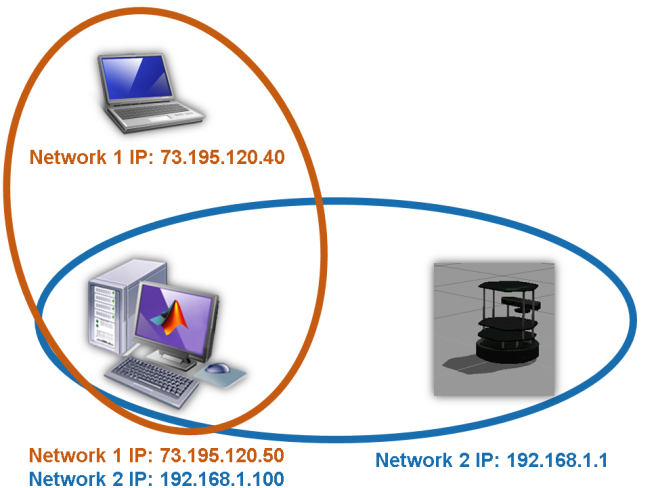

When [`rosinit`](docid:ros_ref.bupf5_j_1) is invoked with the ROS Master IP address (Network 2), it tries to detect the network interface used to contact the master and use that as the IP address for the global node. It will also require your host's IP address to connect to the global node (Network 1). 

These commands advertise your computer's IP address to the ROS network as `192.168.1.100`.

Once a node is registered in the ROS network, you can see the address that it advertises by using the command [`rosnode`](docid:ros_ref.bupf5_j_4)` info ``<nodename>`. You can see the names of all registered nodes by calling `rosnode list`.

## Verify Connection

For your ROS connection to work correctly, you must ensure that all nodes can communicate with the master and with each other. The individual nodes must communicate with the master to register subscribers, publishers, and services. They must also be able to communicate with one another to send and receive data. If your ROS network is not set up correctly, it is possible to be able to send data and be unable to receive data (or vice versa).

This diagram shows a ROS Network with a single ROS master and two different nodes that register themselves with the master. Each node contacts the master to find the advertised address of the other node in the ROS network. Once each node knows the other node's address, a data exchange can be established without involvement of the master.